clear; 
M = 12; 
N = input("insert the number of signals: ");
angle_d = 91;
while angle_d > 90 || angle_d < -90
    angle_d = input("insert the AOA of the desired signal in [-90, 90]: ");
    if angle_d > 90 || angle_d < -90
        disp("Wrong angle."); 
    end 
end
AA = zeros(M, N); 
AA(:,1) = exp(-1i*pi*(0:M-1)'*sin(angle_d*pi/180));
angle_i = 91;
for ii=1:N-1
    while angle_i > 90 || angle_i < -90
        angle_i = input("insert the AOA of " + ii + " the interfering signal in [-90, 90]: "); 
        if angle_i > 90 || angle_i < -90
            disp("Wrong angle."); 
        else 
            AA(:,ii+1) = exp(-1i*pi*(0:M-1)'*sin(angle_i*pi/180));
        end 
    end    
    angle_i = 91;
end 

b = zeros(N,1); 
b(1) = M; 

[U, S, V] = svd(AA.');
% matrice dei valori singolari quadrata
S_inv = 1./diag(S(1:N,1:N)); 
% colonne di V relative ai valori singolari diversi da 0
V_bar = V(:, 1:N); 
w = V_bar*diag(S_inv)*U'*b;


Stampa risultati

% calcolo e plotto il radiation pattern (in dB)
theta = linspace(-90,90,1001);
AF = w.'*exp(-1i.*pi.*(0:M-1)'*sind(theta));

figure;
plot(theta, 20.*log10(abs(AF)./max(abs(AF))));

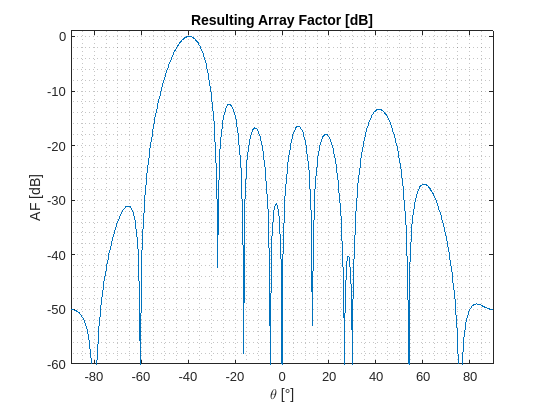

grid minor; 
xlabel('\theta [°]')
ylabel('AF [dB]')
axis([-90 90 -60 1])
title('Resulting Array Factor [dB]')

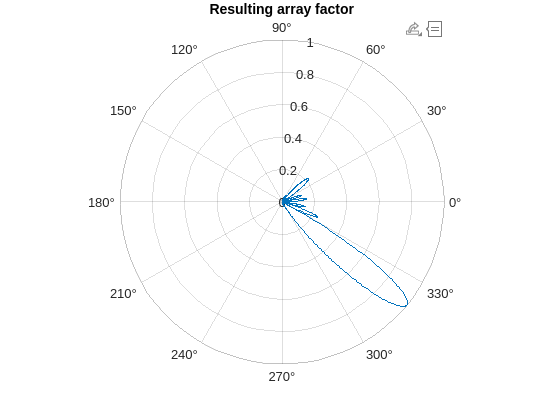

figure; 
polarplot(deg2rad(theta), abs(AF)./max(abs(AF)))
title('Resulting array factor')